  [matlab project] svm, rf 분류기 만들기

1.데이터 불러오기

T=readtable('/MATLAB Drive/matlab 공모전/TTdata.csv');
f1 = T{:,'reye_ratio'}

f1 =     0.2775
    0.2775
    0.2775
    0.2775
    0.2630
    0.2891
    0.2775
    0.2936
    0.2775
    0.3084


f2 = T{:,'leye_ratio'}

f2 =     0.2911
    0.2936
    0.2911
    0.2936
    0.2911
    0.3049
    0.2775
    0.2936
    0.2951
    0.3039


f3 = T{:, 'eye_angle'}

f3 =    -0.9596
   -0.9742
   -0.9596
   -0.9742
   -0.9612
   -0.9769
   -0.9756
   -0.9727
   -0.9857
   -0.9920


f4 = T{:, 'nose_ratio'}

f4 =     0.4877
    0.4877
    0.4877
    0.4877
    0.4877
    0.5122
    0.4877
    0.4877
    0.4877
    0.4887


f5 = T{:, 'chin_sharp'}

f5 =    -0.3264
   -0.3264
   -0.3628
   -0.3246
   -0.3821
   -0.3773
   -0.3897
   -0.3246
   -0.3313
   -0.3518


<<<중요! 원핫인코딩 라벨 불러오기>>>softmax는 원핫.

X= [f1,f2,f3,f4,f5]

X =     0.2775    0.2911   -0.9596    0.4877   -0.3264
    0.2775    0.2936   -0.9742    0.4877   -0.3264
    0.2775    0.2911   -0.9596    0.4877   -0.3628
    0.2775    0.2936   -0.9742    0.4877   -0.3246
    0.2630    0.2911   -0.9612    0.4877   -0.3821
    0.2891    0.3049   -0.9769    0.5122   -0.3773
    0.2775    0.2775   -0.9756    0.4877   -0.3897
    0.2936    0.2936   -0.9727    0.4877   -0.3246
    0.2775    0.2951   -0.9857    0.4877   -0.3313
    0.3084    0.3039   -0.9920    0.4887   -0.3518


y=T{:,'tal'}

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


save('TTdata.mat','X','y')

2. 데이터 스플릿

%training set, 0% validation set and 30% test set.
[train_idx, ~, test_idx] = dividerand(14630, 0.8,0.0,0.2);
x_train = X(train_idx, :);
y_train = y(train_idx);
x_test = X(test_idx, :);
y_test = y(test_idx);

3. SVM CECO 모델 만들기

t = templateSVM('Standardize',true)

t = 피팅할 템플릿 대상 classification SVM.

                     Alpha: [0×1 double]
             BoxConstraint: []
                 CacheSize: []
             CachingMethod: ''
                ClipAlphas: []
    DeltaGradientTolerance: []
                   Epsilon: []
              GapTolerance: []
              KKTTolerance: []
            IterationLimit: []
            KernelFunction: ''
               KernelScale: []
              KernelOffset: []
     KernelPolynomialOrder: []
                  NumPrint: []
                        Nu: []
           OutlierFraction: []
          RemoveDuplicates: []
           ShrinkagePeriod: []
                    Solver: ''
           StandardizeData: 1
        SaveSupportVectors: []
            VerbosityLevel: []
                   Version: 2
                    Method: 'SVM'
                      Type: 'classification'


svm_ecoc = fitcecoc(x_train,y_train);

4.  SVM-ECOC의 클래스는 0-3, 커널 파라미터는 struct값 그대로이다.

talname = svm_ecoc.ClassNames

talname =      0
     1
     2
     3


svm -ecoc 모델 하이퍼파라미터

svm_ecoc.BinaryLearners{1}

ans =   CompactClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [-1 1]
           ScoreTransform: 'none'
                     Beta: [5×1 double]
                     Bias: 6.5308
         KernelParameters: [1×1 struct]


  Properties, Methods


svm-ecoc 모델 로스 결과

error = resubLoss(svm_ecoc)

error = 0.2434

4 SVM CECO 교차검증

CVsvm_1 = crossval(svm_ecoc);

5. 교차검증 확인하기

genError = kfoldLoss(CVsvm_1)

genError = 0.2440

6. SVM_ECOC 2926장 테스트셋(0.2) 예측

pred_svm_ecoc = svm_ecoc.predict(x_test)

pred_svm_ecoc =      0
     0
     0
     0
     0
     3
     3
     3
     3
     3


7.  SVM_ECOC 로스와 오차행렬

svmecocResubErr = resubLoss(svm_ecoc)

svmecocResubErr = 0.2434

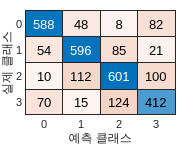

svm_ecocCM = confusionchart(y_test,pred_svm_ecoc);

[8. SVM cidscr] : 훈련데이터에 대한 오분류. 테스트 데이터 predict 없음.

%ficdiscr 함수 모델링 결과 : 아래와 같다.
figure
svm_c = fitcdiscr(x_train,y_train)

svm_c =   ClassificationDiscriminant
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3]
           ScoreTransform: 'none'
          NumObservations: 11704
              DiscrimType: 'linear'
                       Mu: [4×5 double]
                   Coeffs: [4×4 struct]


  Properties, Methods


pred_svm_c = resubPredict(svm_c)

pred_svm_c =      0
     0
     0
     0
     0
     0
     3
     3
     3
     0


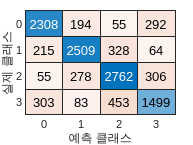

svm_cCM = confusionchart(y_train,pred_svm_c);

svm_cResubErr = resubLoss(svm_c)

svm_cResubErr = 0.2244

6. SVM -ceco 최적화하기(c는 교차검증할 데이터, 훈련데이터의 일부이다)

%rng default
%svm_op = fitcecoc(x_train,y_train,'OptimizeHyperparameters','auto',...
%    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
%    'expected-improvement-plus'))